# Homework 2- Risk Management

### Sommario

Si vogliono confrontare diverse strategie di hedging per far fronte ad una variazione nella struttura dei tassi. Si suppone di possedere un portafoglio costituito da un singolo bond con pagamento di cedole. Si considera inoltre, la formula proposta per descrivere la struttura dei tassi da Nelson e Siegel e, la sua estensione, formulata invece da Svensson. Le diverse strategie di hedging analizzate in seguito sono: un singolo zero con maturità pari a quella del bond, un portafoglio di zeri ed infine uno swap. Lo scopo finale è valutare e confrontare l’effetto di queste diverse politiche in seguito ad una variazione dei parametri che definiscono in modo univoco la curva dei tassi. Per farlo, introduciamo alcune misure di rischio che possono essere utili per la valutazione, come il V@R o il CV@R. Per le simulazioni, si fanno delle assunzioni semplicistiche come il fatto che le perturbazioni seguano una distribuzione normale e che siano indipendenti. Tuttavia, si possono comunque trarre delle conclusioni, infatti, come ci si potrebbe facilmente aspettare, un singolo zero non è in grado di fornire una copertura adeguata, mentre un singolo swap si comporta meglio da questo punto di vista. Se però siamo interessati ad usare solamente degli zeri come strumenti di hedging, la situazione sembra migliorare quando andiamo a considerare un portafoglio di zeri.

### Introduzione

Lo scopo di questo progetto è quello di confrontare diverse politiche di copertura per un portafoglio costituito da bond semplici, al variare della curva dei tassi. Tra gli strumenti di hedging, che possiamo utilizzare, scegliamo degli zeri o eventualmente altri bond che pagano cedole, e degli swap vaniglia. Quest’ultimo, può essere visto come un accordo tra due controparti che si scambiano flussi di cassa periodici, come se fossero degli interessi su un valore nominale. In uno swap sono presenti due “gambe”:

- Quella *fissa,*asssociata al flusso di cassa relativo al tasso di interesse fisso

- Quella *floating*, associata al flusso di cassa relativo al tasso di interesse variabile

Per iniziare ad avere una sensitività del problema, siamo partiti dagli esempi 6.7 e 6.8 presenti nel libro di Lionel Martellini, Philippe Priaulet e Stephane Priaulet*, “Fixed-income securities: Valuation, Risk Management and Portfolio Strategies”,* John Wiley & Sons, Maggio 2003. Nello specifico nell’esempio, immaginiamo di trovarci al tempo t=0 e di conoscere gli specifici parametri che andranno a definire la struttura dei tassi per scadenza. Infatti, come riportato nel libro, nel 1987 Nelson e Siegel hanno proposto di modellare il tasso di capitalizzazione nel continuo di un bond a cedola zero con maturità T, al tempo zero con la seguente funzione:

$\beta_0+\beta_1 \left[ \frac {1-exp\left(-\frac{T}{\tau_1}\right)}{\frac{T}{\tau_1}} \right]+ \beta_2 \left[ \frac {1-exp\left(-\frac{T}{\tau_1}\right)}{\frac{T}{\tau_1}} -exp \left( \frac{T}{\tau_1}\right) \right]$.

Successivamente nel 1994, Svensson propose di migliorare ed estendere questa formula per permettere una maggiore flessibilità ed includere delle forme più complesse per le curve dei tassi per scadenza. La formula modificata diventa:

$\beta_0+\beta_1 \left[ \frac {1-exp\left(-\frac{T}{\tau_1}\right)}{\frac{T}{\tau_1}} \right]+ \beta_2 \left[ \frac {1-exp\left(-\frac{T}{\tau_1}\right)}{\frac{T}{\tau_1}} -exp \left( \frac{T}{\tau_1}\right) \right]+ \beta_3 \left[ \frac {1-exp\left(-\frac{T}{\tau_2}\right)}{\frac{T}{\tau_2}} -exp \left( \frac{T}{\tau_2}\right) \right]$.

In queste formule, il parametro $\beta_0$rappresenta il limite per il tasso quando la maturità tende a +$\infty$, quindi possiamo considerarlo come un tasso di interesse a lungo termine e rappresenta l’intersezione della curva con l’asse delle ordinate (pendenza della retta nel caso più semplice), quindi al variare di questo parametro, sta variando l’altezza della curva. 

Invece il parametro $\beta_1$  rappresenta il limite per il tasso a cui sottraiamo $\beta_0$  , quando la maturità tende a zero. Questo termine può essere considerato come uno spread tra il lungo e il breve periodo ed è collegato in qualche modo alla pendenza della curva.

Mentre i parametri $\beta_2$ e  $\beta_3$  sono collegati alla curvatura. Infine, i parametri $\tau_1$  e  $\tau_2$ sono parametri di scala che misurano il tasso con cui le componenti di breve e medio termine decadono a zero.

Comunque, in entrambi i casi, vediamo che l’evoluzione dei tassi è completamente determinata dal valore dei parametri beta, quando i parametri di scala vengono fissati. Questo significa che in realtà gli unici fattori di rischio legati al rendimento di un bond o di un portafoglio saranno solamente 4, e nello specifico solamente il vettore dei parametri beta. Questo modello è quindi molto utile quando consideriamo dei bond che hanno una maturità lunga e che magari pagano cedole più volte in un anno, ad esempio per un bond con maturità 20 anni che paga cedole semestrali, utilizzando questo modello, i fattori di rischio da 40 si riducono a 4.

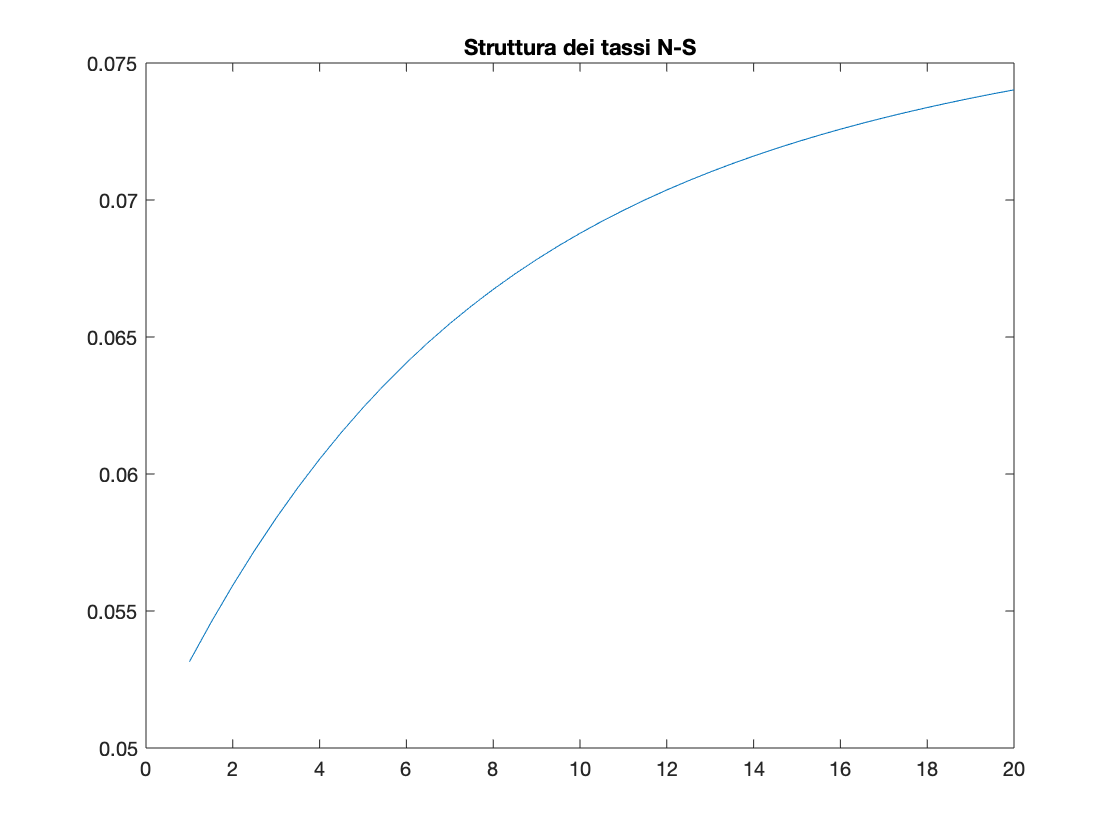

clc
clear all
close all
format bank
t_0=0;


beta_0=0.08; %valori di beta presi dall'esempio di Martellini
beta_1=-0.03;
beta_2=-0.01;
tau_1=3;

r= @(betaValues,tau,T) betaValues(1)...
    +betaValues(2)*((1-exp(-T/tau(1)))/(T/tau(1)))...
    +betaValues(3)*((1-exp(-T/tau(1)))/(T/tau(1))-exp(-T/tau(1)))...
    +betaValues(4)*((1-exp(-T/tau(2)))/(T/tau(2))-exp(-T/tau(2)));
%metto beta_3 = 0 e tau_2 = 1 così non influenzano il risultato
betaValues=[beta_0 beta_1 beta_2 0];
tau=[tau_1 1];

figure
maturities = 1:0.5:20;
tassi = zeros(1,length(maturities));
for i = 1:length(maturities)
    tassi(i) = r(betaValues,tau,maturities(i));
end
plot(maturities,tassi)
title('Struttura dei tassi N-S')

### *Hedging di un bond con uno zero*

Consideriamo nello specifico, inizialmente un portafoglio da immunizzare costituito da solamente un bond. In tutto il progetto immaginiamo che i portafogli, i bond e gli swap, abbiano sempre una struttura ben precisa in modo da essere passati come argomento di input alle diverse funzioni. Nello specifico, ogni portafoglio ha alcuni elementi di base che lo caratterizzano, quindi consideriamo un vettore in cui elementi, nell’ordine rappresentano:

- Il numero di bond diversi da cui è costituito il portafoglio (se si tratta di un unico bond questo valore sarà pari ad 1)

- Il numero di bond di ciascun tipo presenti nel portafoglio (se ci sono due bond nel portafoglio il primo numero rappresenterà il numero di bond di tipo 1 presenti nel portafoglio, mentre il secondo quelli di tipo 2)

Dopo di questi parametri iniziali ci saranno tanti vettori di lunghezza 4, quanti sono i diversi bond e queste sono le caratteristiche vere e proprie di un bond.

- La maturità T espressa in anni

- Il valore nominale o Face Value

- Il tasso di cedola annuale (se si tratta di uno zero ovviamente questo parametro sarà nullo)

- Il numero di pagamenti in un anno (per convenzioni di mercato supponiamo che il pagamento di cedole sia semestrale).

In particolare, consideriamo un bond e uno zero e chiamiamo la funzione *fixed_duration* per calcolare le diverse sensitività utilizzando prima la formula per i tassi di Nelson e Siegel, perché imponiamo che $\beta_3$  sia nullo, e poi con la formula migliorata di Svensson. Per il bond che paga cedole, possiamo osservare che la dollar duration (o $\beta_0$ duration) vale -192.51 $, e possiamo interpretare questo dato andando ad affermare che per una crescita dell'1% del parametro $\beta_0$, il prezzo del nostro bond diminuisce di 1.92 $. Mentre per una variazione dell'1% del parametro $\beta_2$ abbiamo una variazione solamente di -0.41 $. 

Per semplicità, assumiamo che il nostro portafoglio da coprire sia costituito da un singolo bond, ma in caso avessimo voluto coprire un portafoglio, tutti i ragionamenti si potrebbero ripetere in modo analogo.

A questo punto scegliamo di coprire il nostro bond con lo zero che abbiamo definito. Questo vuol dire, che a fronte dei 3 (e successivamente 4) fattori di rischio che stiamo considerando nella curva dei tassi, ci stiamo coprendo utilizzando un solo strumento di hedging e questo ovviamente mostra le proprie limitazioni. Per coprire il nostro bond con lo zero andiamo a calcolare la quantità $\phi$ da investire nello zero, andando ad imporre che le dollar duration del bond e dello zero siano uguali. 

bond=[1, 1, 2, 100, 0.05, 1];
zero=[1, 1, 0.5, 100, 0, 1]; 
[price, D0bond, D1bond, D2bond]=fixed_duration(t_0, bond, r, tau, betaValues)

price =          98.63


D0bond =        -192.51


D1bond =        -141.08


D2bond =         -41.28


[~, D0zero, ~, ~]=fixed_duration(t_0, zero, r, tau, betaValues);
phiNS = - D0bond/D0zero

phiNS =          -3.95


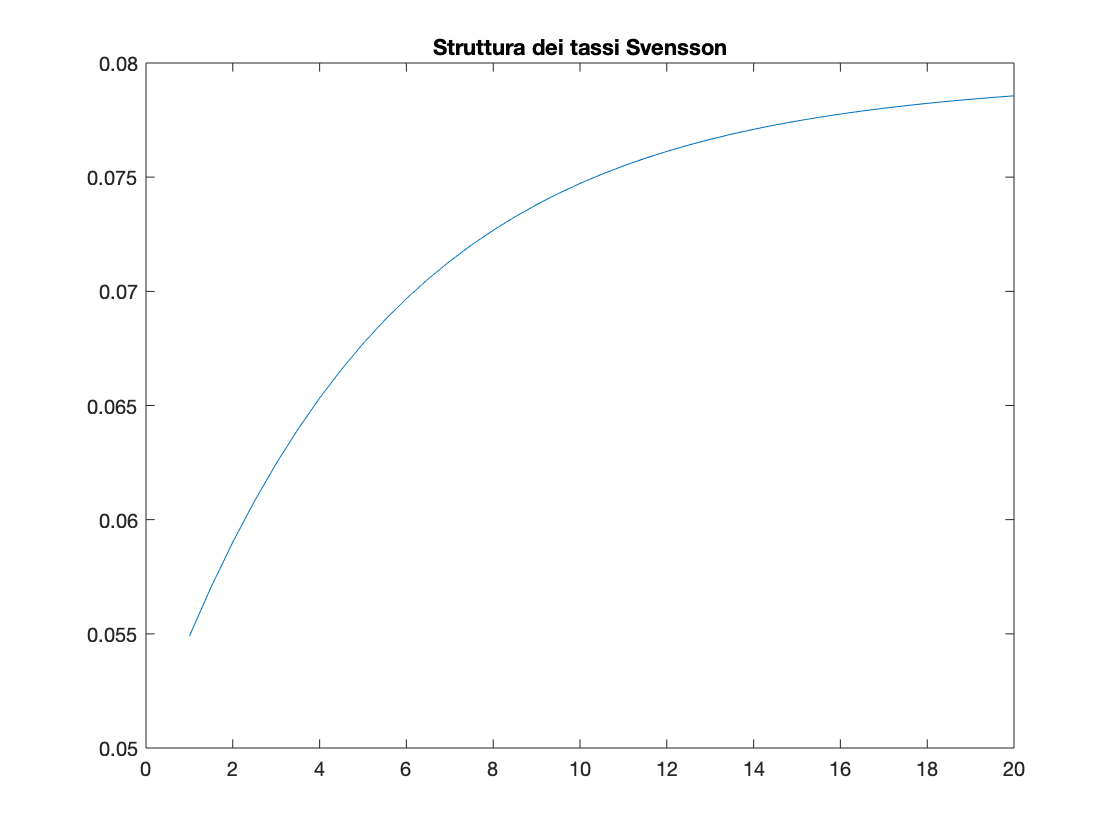


%Svensson
beta_3=0.02;
tau_2=5;
betaValues=[beta_0 beta_1 beta_2 beta_3];
tau=[tau_1,tau_2];

figure
maturities = 1:0.5:20;
tassi = zeros(1,length(maturities));
for i = 1:length(maturities)
    tassi(i) = r(betaValues,tau,maturities(i));
end
plot(maturities,tassi)
title('Struttura dei tassi Svensson')


%tau = [5,8];
%bond=[1, 1, 5, 10000, 0.05, 2];
%zero=[1, 1, 0.5, 10000, 0, 2]; %capitalizzazione diversa da zero altrimenti errore, rimane uno zeroCouponBond perché coupon = 0% 
[~, D0bond, ~, ~]=fixed_duration(t_0, bond, r, tau, betaValues);
[~, D0zero, ~, ~]=fixed_duration(t_0, zero, r, tau, betaValues);
phi = - D0bond/D0zero

phi =          -3.93


Da adesso in poi, supponiamo che il parametro $\beta_3$ sia diverso da zero e quindi utilizzeremo la formula proposta da Svensson. Vediamo ora cosa accade quando abbiamo una variazione nella struttura dei tassi, andando a chiamare la funzione *portfolioShock*. Inizialmente consideriamo una variazione solo sul primo parametro, quindi su $\beta_0$, questo vuol dire che stiamo considerando uno shock parallelo nella curva dei tassi, in particolare una traslazione verso l'alto. Quindi ci aspettiamo che il valore del portafoglio dimuisca, come effettivamente verifichiamo. Calcolando la variazione tra il valore del portafoglio protetto e il valore del bond prima della variazione, in realtà osserviamo un guadagno. Questo è un aspetto positivo, tuttavia bisogna porre l'attenzione sul fatto che abbiamo considerato uno shock parallelo e quindi utilizzando un solo strumento di hedging, riusciamo a coprirci abbastanza bene.

hedge = zero;
%variazione di beta_0
betaVariation = [0.06 0 0 0];
[newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation,phi);
percProfit = (newValuePosition-priceBondOriginal)/priceBondOriginal*100

percProfit =           0.49


percProfitNoHedge = (priceBondNew-priceBondOriginal)/priceBondOriginal*100

percProfitNoHedge =         -11.04


Vediamo ora cosa accade facendo variare gli altri beta. In queste situazioni sto facendo variare la pendenza e la curvatura della struttura dei tassi, quindi mi aspetto non essere più in grado di coprirmi andando ad utilizzare un unico zero come strumento di hedging. 

Infatti, osserviamo che facendo hedging quando c'è una riduzione del parametro $\beta_1$ perdiamo, mentre avremmo guadagnato se non avessimo fatto hedging. Simile alla situazione in cui diminuisce il parametro $\beta_{3\;} ,$ in cui comunque facendo hedging guardagnamo di meno rispetto a quando scegliamo di non coprirci, ma comunque guadagnamo in minima parte. Facendo invece aumentare il parametro $\beta_2 ,$ comunque stiamo perdendo in entrambi i casi, ma sembra che siamo protetti almeno parzialmente con il nostro zero.

%variazione di beta_1
betaVariation = [0 -0.08 0 0];
[newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation,phi);
percProfit = (newValuePosition-priceBondOriginal)/priceBondOriginal*100

percProfit =          -2.52


percProfitNoHedge = (priceBondNew-priceBondOriginal)/priceBondOriginal*100

percProfitNoHedge =          12.13


%variazione di beta_2
betaVariation = [0 0 0.03 0];
[newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation,phi);
percProfit = (newValuePosition-priceBondOriginal)/priceBondOriginal*100

percProfit =          -0.81


percProfitNoHedge = (priceBondNew-priceBondOriginal)/priceBondOriginal*100

percProfitNoHedge =          -1.25


%variazione di beta_3
betaVariation = [0 0 0 -0.07];
[newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation,phi);
percProfit = (newValuePosition-priceBondOriginal)/priceBondOriginal*100

percProfit =           1.46


percProfitNoHedge = (priceBondNew-priceBondOriginal)/priceBondOriginal*100

percProfitNoHedge =           2.10


### *Hedging di un bond con più zeri*

Dopo aver osservato che la copertura con un solo zero non ci protegge molto neanche per le variazioni piuttosto semplici (stiamo supponendo che cambi un parametro alla volta, ma questa situazione risulta essere abbastanza irrealistica), e aver capito che i nostri fattori di rischio in questa situazione sono quattro, vediamo cosa accade ammettendo di avere a disposizione più strumenti di hedging. Nello specifico, ci aspetteremmo che utilizzando 4 strumenti e in questo caso 4 zeri tutti dello stesso tipo che però hanno delle maturità diverse, saremo più coperti rispetto al caso precedente. Notiamo inoltre che quando viene applicata una variazione sempre pari ad 800 punti base, abbiamo alcuni casi anche un guadagno, ma sicuramente una perdita inferiore rispetto a quando scelgo di non fare hedging. In questo caso il bond che vogliamo coprire ha una maturità di 2 anni, quindi è ancora possibile (o comunque plausibile) trovare uno zero che abbia una maturità corrispondente al momento in cui viene pagata una cedola del bond da coprire, se invece dovessimo avere un bond con una maturità più lunga, sarebbe molto difficile trovare degli zero con delle maturità più lunghe. Tuttavia ci aspettiamo comunque di essere suffcientemente coperti anche in questo secondo caso.

[priceP, D0P, D1P, D2P, D3P]=fixed_duration(t_0, bond, r, tau, betaValues);
portfolio_sensitivities = [D0P;D1P;D2P;D3P];

zero1=[4, 1, 1, 1, 1, 0.5, 100, 0, 1];
zero2=[1, 100, 0, 1]; 
zero3=[1.5, 100, 0, 1];
zero4=[2, 100, 0, 1];
hedge1 = [zero1, zero2, zero3, zero4];

[~, D_0, D_1, D_2, D_3]=fixed_duration(0, hedge1, r, tau, betaValues);
asset_sentitivities = [D_0, D_1, D_2, D_3];

phi1 = asset_sentitivities'\(-portfolio_sensitivities)

phi1 =         -79.40



s=table('Size', [4 2],'VariableTypes', {'double','double'},...
    'VariableNames', {'Hedge', 'No_hedge'},'RowNames', {'beta_0', 'beta_1', 'beta_2', 'beta_3'});
for i=1:4
    betaVariation=zeros(1, 4);
    betaVariation(1, i)=0.08;
    [newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge1,r,tau,betaValues,betaVariation,phi1);
    s{i,1} = (newValuePosition-priceBondOriginal)/priceBondOriginal*100;
    s{i, 2} = (priceBondNew-priceBondOriginal)/priceBondOriginal*100;
end
s

s = 4×2 table
              Hedge    No_hedge
              _____    ________

    beta_0     0.13     -29.62 
    beta_1     7.54     -16.36 
    beta_2    -4.44      -9.85 
    beta_3    -4.96      -8.70 


## *Variazioni normali nella struttura dei tassi per un bond*

Le diverse casistiche analizzate fino a questo momento sono piuttosto irrealistiche come detto più volte. Un primo metodo che è possibile utilizzare per migliorare questa situazione è simulare delle variazioni andando a campionare da una distribuzione normale i cui parametri di media e varianza vengono scelti arbitrariamente. Chiaramente è ancora un metodo troppo semplificato perché stiamo simulando i diversi tassi di una struttura per scadenza quindi sicuramente non varrà l'ipotesi di indipendenza tra due tassi per diverse maturità, ma in qualche modo dovrebbero essere collegati. Ad ogni modo, vediamo come si comporta il nostro portafoglio di copertura in questo caso. Nell'immagine è possibile osservare la struttura dei tassi calcolati utilizzando la formula di Svensson.

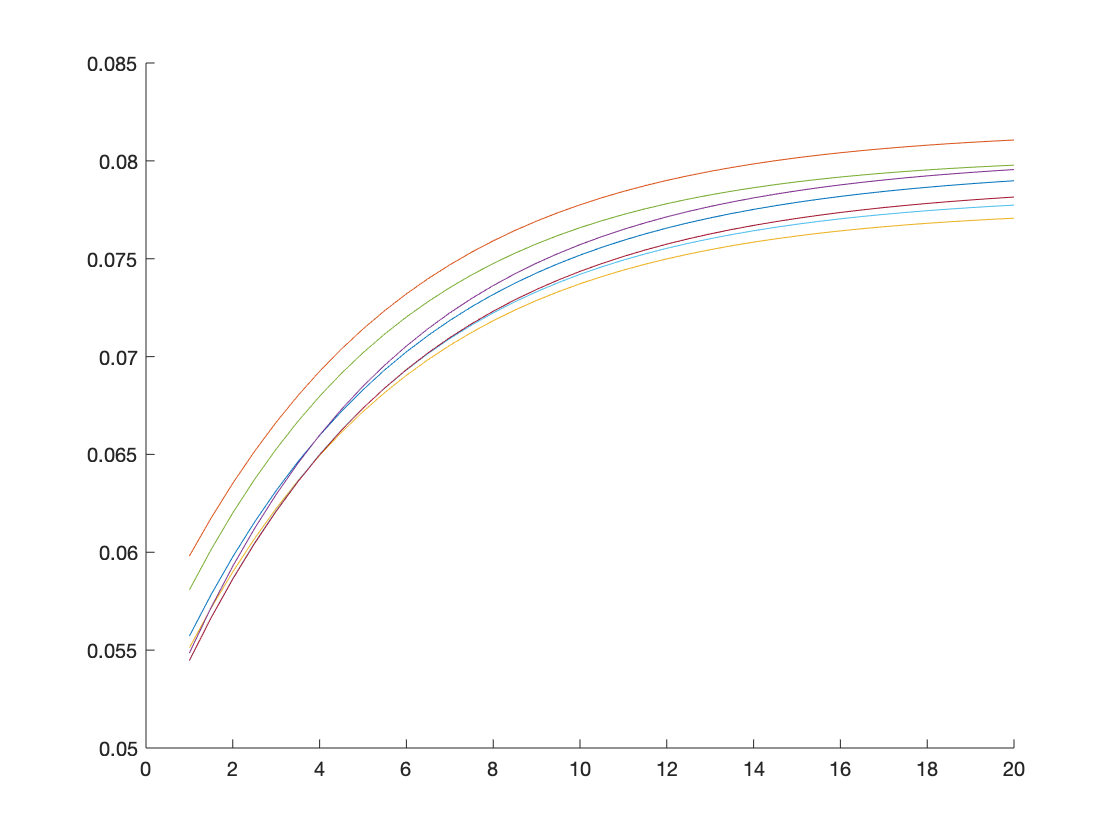


%struttura dei tassi per alcune variazioni dei beta
seed = 'default';
num_scenari = 7;
mu = zeros(1,4);
sigma = 0.001;
Sigma = eye(4)*(sigma^2);
rng(seed) % For reproducibility
betaVariation = mvnrnd(mu,Sigma,num_scenari);
hedge=zero;
figure
maturities = 1:0.5:20;
betaValues = [0.08,-0.03,-0.01,0.02];
for j = 1:size(betaVariation,1)
    hold on
    tassi = zeros(1,length(maturities));
    for i = 1:length(maturities)
        tassi(i) = r(betaValues+betaVariation(j,:),tau,maturities(i));
    end
    plot(maturities,tassi)
end

Per capire cosa accade, andando ad assumere che le variazioni nelle singole siano indipendenti e identicamente distribuite secondo una normale con vettore delle medie il vettore nullo e proviamo diversi valori di deviazione standard (0.001, 0.002, 0.004). Ovviamente poiché i diversi parametri vengono assunti indipendenti la matrice di varianza e covarianza, sarà una matrice diagonale dove gli elementi diversi da zero saranno appunto le varianze. Campioniamo da una normale tanti campioni quanti ne indichiamo nella variabile *num_scenari *e confrontiamo cosa accade nelle tre diverse situazioni all'aumentare della variabilità. Ritorniamo a considerare il nostro bond di partenza e assumiamo di voler vedere cosa accade quando scegliamo come strumento di hedging lo zero di partenza. Com'è possibile osservare facilmente dai grafici, dove stiamo confrontando la percentuale del profitto a seconda che scegliamo di fare o meno hedging, in questo caso siamo abbastanza coperti quando la deviazione standard (e di conseguenza la varianza) è piccola, ma man mano che questa cresce la nostra copertura è sempre meno in grado di proteggerci. Al termine, abbiamo anche inserito alcune misure di rischio che possono risultare utili per avere un’idea del problema. Se consideriamo il caso in cui la deviazione standard è più grande, vediamo che il V@R nel caso in cui scegliamo di fare hedging, ci suggerisce che nel 5% dei casi dovremmo attenderci una perdita di circa il 32% e che nell’1% dei casi questa aumenta fino al 46%. Sono numeri molto alti, tuttavia sicuramente minori di quelli che si ottengono senza andare a fare hedging. Tuttavia il V@R non è in grado di darci informazioni sull’entità della perdita, per questo andiamo a considerare il CV@R. **(SONO TROPPO ALTI QUESTI NUMERI??)**

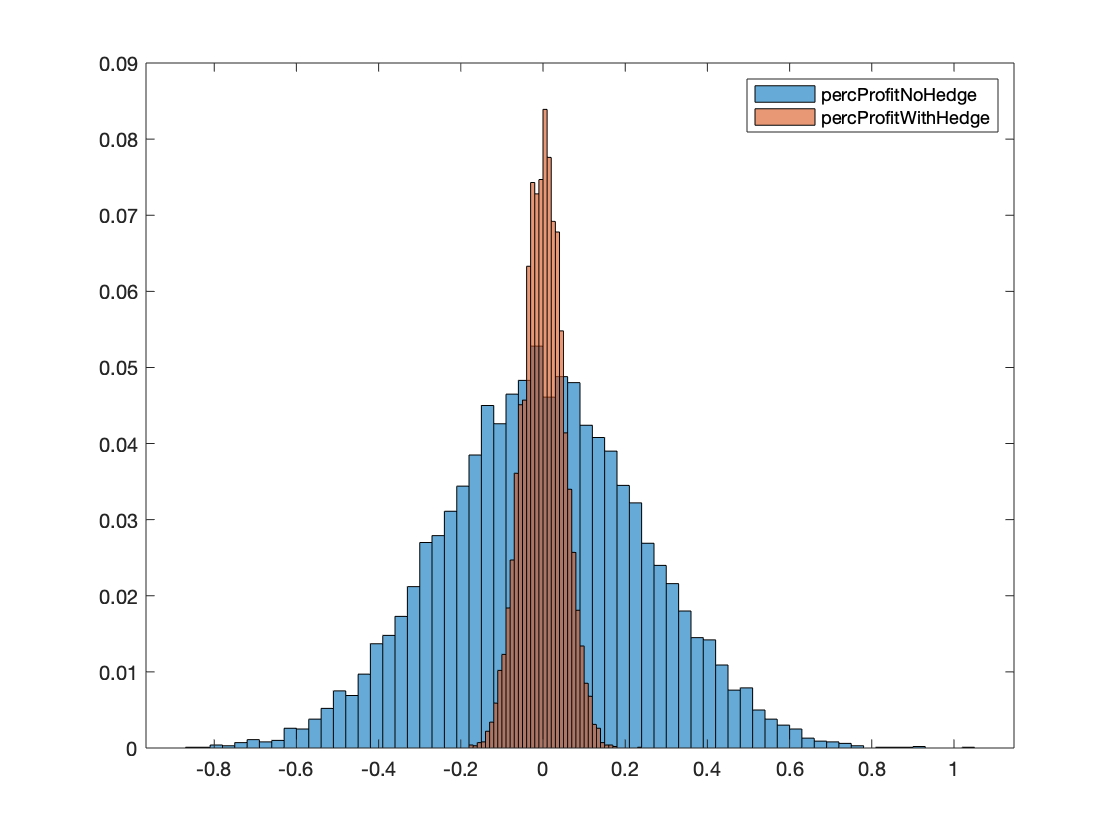

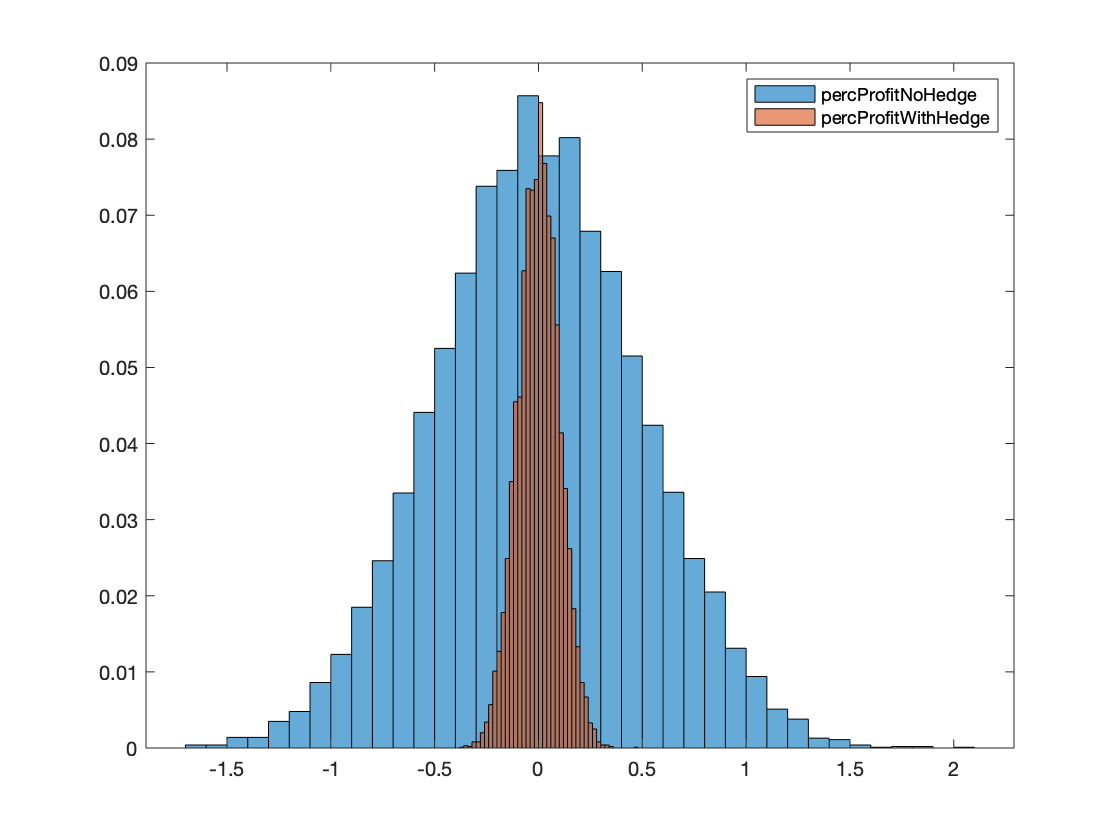

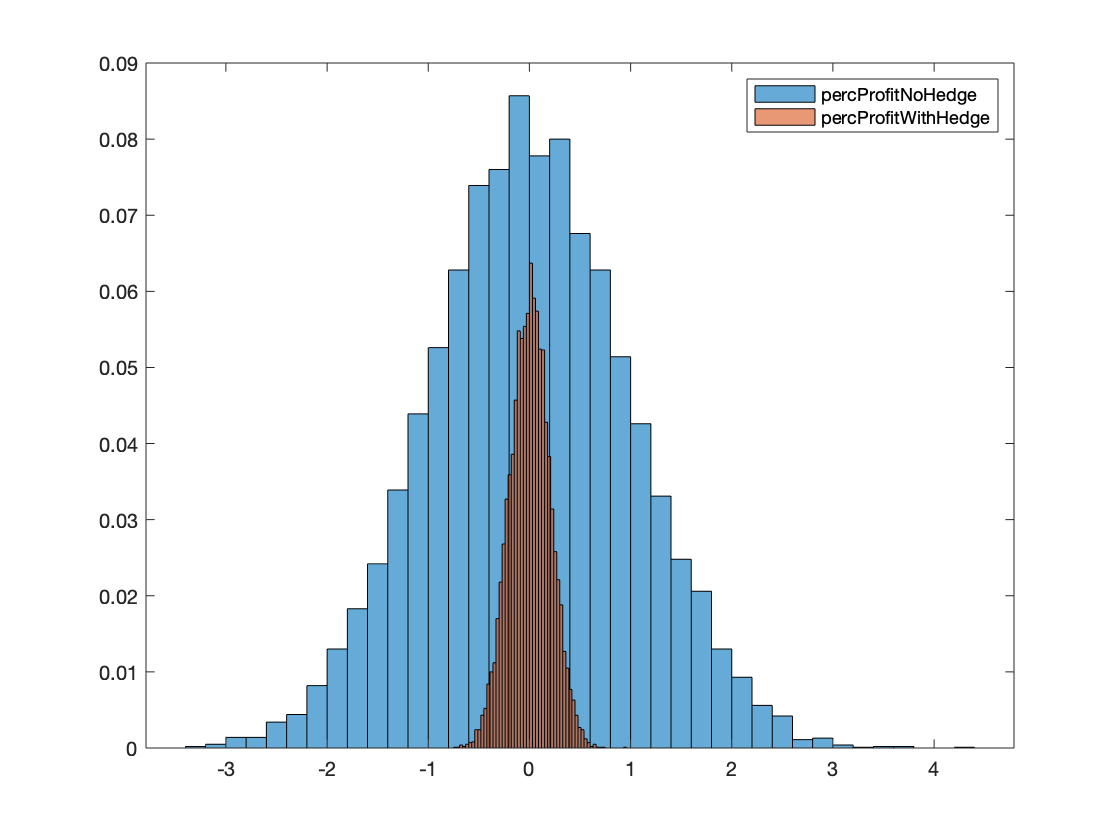

T=table('RowNames',{'VaR','VarNoHedge','CVaR','CVarNoHedge'});
probabilities = [0.90 0.95 0.99];
%proviamo con vari valori di deviazione standard
scale = [1,2,4];
tab = zeros(4,length(probabilities));
VaR = zeros(1,length(probabilities));
VaRNoHedge = zeros(1,length(probabilities));
CVaR = zeros(1,length(probabilities));
CVaRNoHedge = zeros(1,length(probabilities));
for diff = 1:length(scale)
    seed = 'default';
    num_scenari = 10000;%10000
    mu = zeros(1,4);
    sigma = 0.001*scale(diff);
    Sigma = eye(4)*(sigma^2);
    rng(seed) % For reproducibility
    betaVariation = mvnrnd(mu,Sigma,num_scenari);
    
    percProfit = zeros(num_scenari,1);
    percProfitNoHedge = zeros(num_scenari,1);
    for s = 1:num_scenari
        [newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation(s,:),phi);
        percProfit(s) = (newValuePosition-priceBondOriginal)/priceBondOriginal*100;
        percProfitNoHedge(s) = (priceBondNew-priceBondOriginal)/priceBondOriginal*100;
    end
    figure
    histogram(percProfitNoHedge,'Normalization','probability')
    hold on
    histogram(percProfit,'Normalization','probability')
    legend('percProfitNoHedge','percProfitWithHedge')
    hold off
    for prob=1:length(probabilities)
        id=floor(num_scenari*(1-probabilities(prob)));
        percProfit_sort = sort(percProfit);
        VaR(prob) = percProfit_sort(id);
        CVaR(prob) = mean(percProfit_sort(1:id));
        percProfitNoHedge_sort = sort(percProfitNoHedge);
        VaRNoHedge(prob) = percProfitNoHedge_sort(id);
        CVaRNoHedge(prob) = mean(percProfitNoHedge_sort(1:id));
    end
    
    tab(1,:) = VaR;
    tab(2,:) = VaRNoHedge;
    tab(3,:) = CVaR;
    tab(4,:) = CVaRNoHedge;
    
    T = addvars(T,tab,'NewVariableNames',num2str(sigma));
end


disp(T)

                            0.001                      0.002                      0.004         
                   _______________________    _______________________    _______________________

    VaR            -0.06    -0.08    -0.12    -0.13    -0.16    -0.23    -0.25    -0.32    -0.46
    VarNoHedge     -0.31    -0.40    -0.57    -0.63    -0.81    -1.13    -1.25    -1.61    -2.24
    CVaR           -0.09    -0.10    -0.13    -0.17    -0.21    -0.26    -0.35    -0.41    -0.53
    CVarNoHedge    -0.43    -0.50    -0.65    -0.86    -1.01    -1.29    -1.71    -2.00    -2.56



### ***Variazioni normali nella struttura dei tassi con un portafoglio di zeri***

Ripetiamo adesso gli stessi ragionamenti fatti nel caso precedente, andando questa volta però a considerare il portafoglio di bond che avevamo costruito per vedere se la situazione migliora.

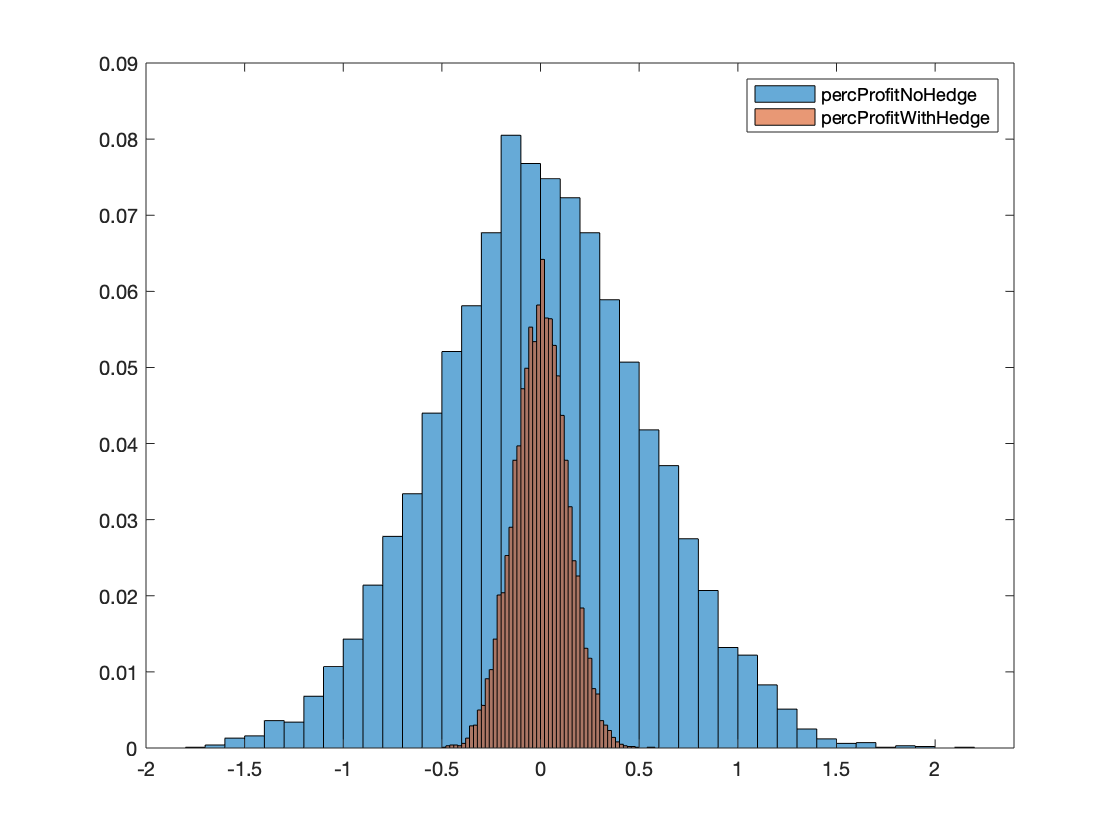

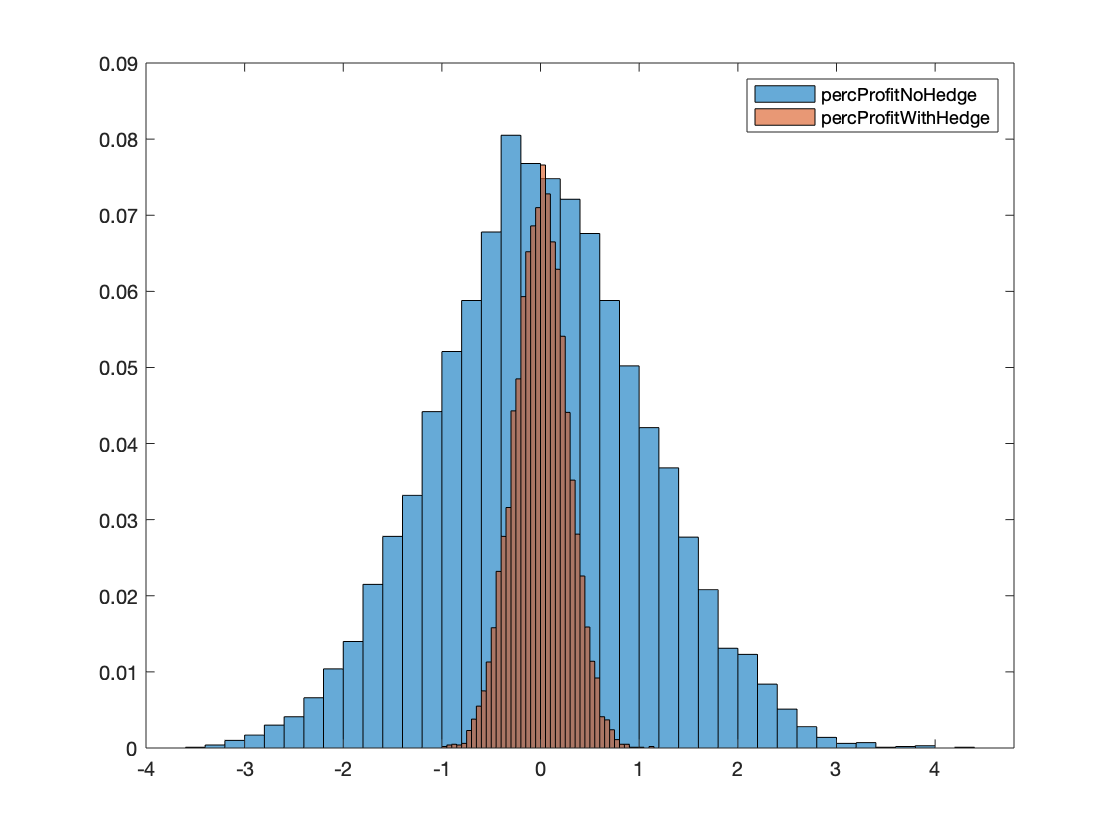

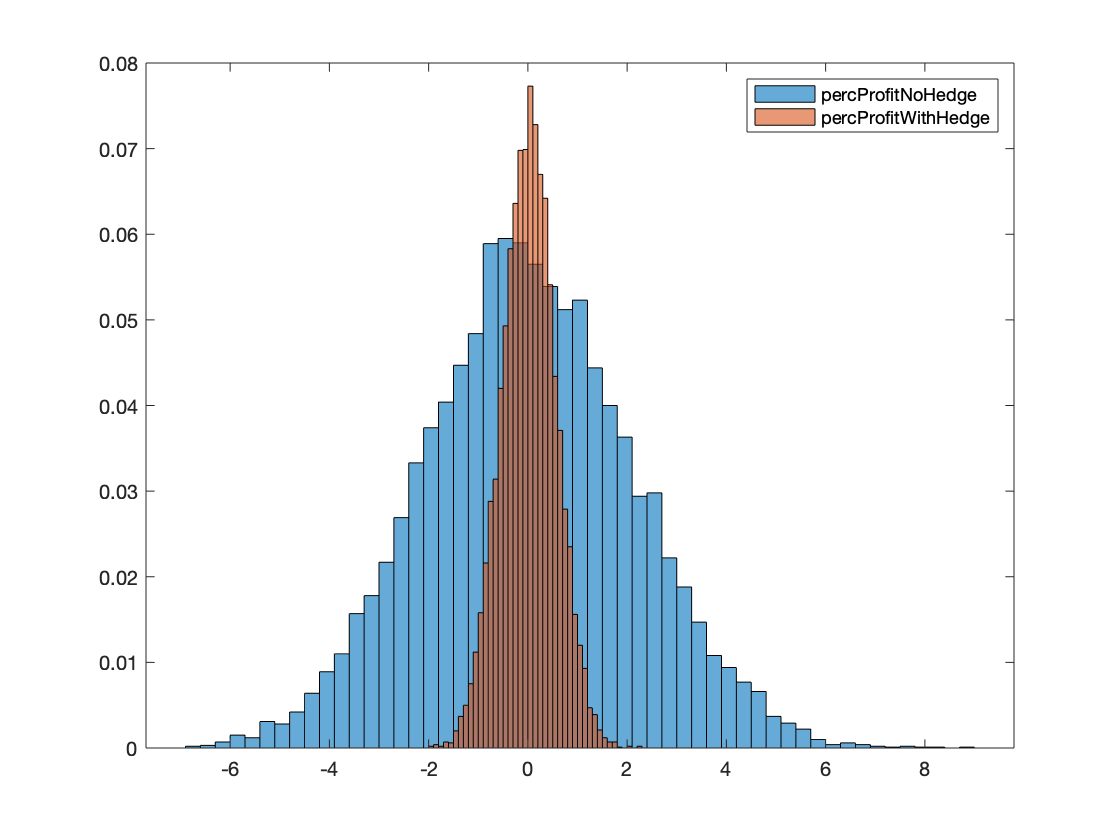

T=table('RowNames',{'VaR','VarNoHedge','CVaR','CVarNoHedge'});
probabilities = [0.90 0.95 0.99];
%proviamo con vari valori di deviazione standard
scale = [1,2,4];
hedge=hedge1;
tab = zeros(4,length(probabilities));
VaR = zeros(1,length(probabilities));
VaRNoHedge = zeros(1,length(probabilities));
CVaR = zeros(1,length(probabilities));
CVaRNoHedge = zeros(1,length(probabilities));
for diff = 1:length(scale)
    seed = 'default';
    num_scenari = 10000;%10000
    mu = zeros(1,4);
    sigma = 0.001*scale(diff);
    Sigma = eye(4)*(sigma^2);
    rng(seed) % For reproducibility
    betaVariation = mvnrnd(mu,Sigma,num_scenari);
    
    percProfit = zeros(num_scenari,1);
    percProfitNoHedge = zeros(num_scenari,1);
    for s = 1:num_scenari
        [newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge1,r,tau,betaValues,betaVariation(s,:),phi1);
        percProfit(s) = (newValuePosition-priceBondOriginal)/priceBondOriginal*100;
        percProfitNoHedge(s) = (priceBondNew-priceBondOriginal)/priceBondOriginal*100;
    end
    figure
    histogram(percProfitNoHedge,'Normalization','probability')
    hold on
    histogram(percProfit,'Normalization','probability')
    legend('percProfitNoHedge','percProfitWithHedge')
    hold off
    for prob=1:length(probabilities)
        id=floor(num_scenari*(1-probabilities(prob)));
        percProfit_sort = sort(percProfit);
        VaR(prob) = percProfit_sort(id);
        CVaR(prob) = mean(percProfit_sort(1:id));
        percProfitNoHedge_sort = sort(percProfitNoHedge);
        VaRNoHedge(prob) = percProfitNoHedge_sort(id);
        CVaRNoHedge(prob) = mean(percProfitNoHedge_sort(1:id));
    end
    
    tab(1,:) = VaR;
    tab(2,:) = VaRNoHedge;
    tab(3,:) = CVaR;
    tab(4,:) = CVaRNoHedge;
    
    T = addvars(T,tab,'NewVariableNames',num2str(sigma));
end

disp(T)

                            0.001                      0.002                      0.004         
                   _______________________    _______________________    _______________________

    VaR            -0.18    -0.22    -0.32    -0.35    -0.45    -0.63    -0.69    -0.89    -1.25
    VarNoHedge     -0.67    -0.86    -1.22    -1.34    -1.72    -2.41    -2.66    -3.40    -4.77
    CVaR           -0.24    -0.28    -0.36    -0.48    -0.56    -0.72    -0.95    -1.11    -1.42
    CVarNoHedge    -0.92    -1.07    -1.38    -1.83    -2.14    -2.74    -3.61    -4.22    -5.39



**(SI PUO' ELIMINARE??)**


%%%%% PORTAFOGLIO CON PIù ELEMENTI

%consideriamo 3 bond diversi ===> 3 fattori di rischio
% b1=[2*12, 100, 0.05,1];
% b2=[7*12, 100, 0.05, 1];
% b3=[15*12, 100, 0.05, 1];
% B1=[1, 1, 2*12, 100, 0.05, 1];
% B2=[1, 1, 7*12, 100, 0.05, 1];
% B3=[1, 1, 15*12, 100, 0.05, 1];
% portfolio=[3, 1, 1, 1, b1, b2, b3];
%[price1, D01, D11, D21]=fixed_duration(t_0, B1, r, 3);
%[price2, D02, D12, D22]=fixed_duration(t_0, B2, r, 3);
%[price3, D03, D13, D23]=fixed_duration(t_0, B3, r, 3);

bond=[1, 1, 5, 10000, 0.05, 2];
[priceP, D0P, D1P, D2P, D3P]=fixed_duration(t_0, bond, r, tau, betaValues);

% bond=[5*12, 10000, 0.05, 2];
% zero=[0.5*12, 10000, 0, 2];
% portfolio=[2, 1, phi, bond, zero];
% [priceP, D0P, D1P, D2P]=fixed_duration(t_0, portfolio, r, tau, betaValues)

% %posso calcolarli con la funzione di prima
portfolio_sensitivities = [D0P;D1P;D2P;D3P];

%treasury bonds as hedging assets
% A1=[3*12, 100, 0.07, 1];
% A2=[7*12, 100, 0.08, 1];
% A3=[12*12, 100, 0.05, 1];
% A4=[18*12, 100, 0.06, 1];
% A1=[0.5*12, 10000, 0, 2];
% A2=[1.0*12, 10000, 0, 2];
% A3=[1.5*12, 10000, 0, 2];
% A4=[2.0*12, 10000, 0, 2];

asset_sentitivities = zeros(4);

% [p, Dl, Ds,Dg ]=fixed_duration(0, [1, 1, A1], r, tau, betaValues);
% asset_durations(:,1) = [Dl, Ds, Dg, p];
% [p, Dl, Ds,Dg ]=fixed_duration(0, [1, 1, A2], r, tau, betaValues);
% asset_durations(:,2) = [Dl, Ds, Dg, p];
% [p, Dl, Ds,Dg ]=fixed_duration(0, [1, 1, A3], r, tau, betaValues);
% asset_durations(:,3) = [Dl, Ds, Dg, p];
% [p, Dl, Ds,Dg ]=fixed_duration(0, [1, 1, A4], r, tau, betaValues);
% asset_durations(:,4) = [Dl, Ds, Dg, p];

% [p, D_0, D_1, D_2, D_3]=fixed_duration(0, [1, 1, A1], r, tau, betaValues);
% asset_sentitivities(:,1) = [D_0, D_1, D_2, D_3];
% [p, D_0, D_1, D_2, D_3]=fixed_duration(0, [1, 1, A2], r, tau, betaValues);
% asset_sentitivities(:,2) = [D_0, D_1, D_2, D_3];
% [p, D_0, D_1, D_2, D_3]=fixed_duration(0, [1, 1, A3], r, tau, betaValues);
% asset_sentitivities(:,3) = [D_0, D_1, D_2, D_3];
% [p, D_0, D_1, D_2, D_3]=fixed_duration(0, [1, 1, A4], r, tau, betaValues);
% asset_sentitivities(:,4) = [D_0, D_1, D_2, D_3];
% phi = asset_sentitivities\(-portfolio_sensitivities)

A1=[1, 1, 0.5, 10000, 0, 2];
A2=[1, 1, 1.0, 10000, 0, 2];
A3=[1, 1, 1.5, 10000, 0, 2];
A4=[1, 1, 2.0, 10000, 0, 2];
[~, D_0, D_1, D_2, D_3]=fixed_duration(0, A1, r, tau, betaValues);
asset_sentitivities(:,1) = [D_0, D_1, D_2, D_3];
[~, D_0, D_1, D_2, D_3]=fixed_duration(0, A2, r, tau, betaValues);
asset_sentitivities(:,2) = [D_0, D_1, D_2, D_3];
[~, D_0, D_1, D_2, D_3]=fixed_duration(0, A3, r, tau, betaValues);
asset_sentitivities(:,3) = [D_0, D_1, D_2, D_3];
[~, D_0, D_1, D_2, D_3]=fixed_duration(0, A4, r, tau, betaValues);
asset_sentitivities(:,4) = [D_0, D_1, D_2, D_3];

phi = asset_sentitivities\(-portfolio_sensitivities)

phi =         220.23
       -415.05
        353.46
       -115.46


## Swap

Una strategia alternativa, invece di coprire con dei bond potrebbe essere quella di utilizzare degli swap. La situazione più semplice da ipotizzare è quella di avere a disposizione uno swap con la stessa maturità del bond da immunizzare ed utilizzare questo come strumento di hedging. Verifichiamo subito che nel momento in cui lo swap viene creato ha, ovviamente, valore nullo. La duration per questo motivo non è definita per uno swap, mentre la dollar duration in questo caso è negativa.

fixed = true;
T = 2;
faceValue = 100;
NPayments = 1;
last_rate = 0.05;
swap=[1, 1, T, faceValue, NaN, NPayments];
[p_swap,Dd_swap] = swap_duration(t_0, swap, r, tau, betaValues, fixed, last_rate)

p_swap =              0


Dd_swap =         -94.26


Consideriamo nuovamente il nostro bond da immunizzare e calcoliamo in quante unità di swap è opportuno investire, ancora andando ad applicare una immunizzazione considerando solamente la dollar duration (derivata rispetto a $\left.\beta_0 \right)$, quindi al primo ordine:

bond=[1, 1, 2, 100, 0.05, 1];
[priceBond, D0bond, D1bond, D2bond]=fixed_duration(t_0, bond, r, tau, betaValues);
phi = - D0bond/Dd_swap

phi =        -436.47


Proviamo a vedere adesso come si comporta lo swap in seguito ad una variazione di $\beta_0$:

betaVariation = [0.01 0 0 0];

hedge = swap;
[newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation,phi,'swap',fixed,last_rate);
percProfit = (newValuePosition-priceBondOriginal)/priceBondOriginal*100

percProfit =          -4.34


percProfitNoHedge = (priceBondNew-priceBondOriginal)/priceBondOriginal*100

percProfitNoHedge =          -4.35


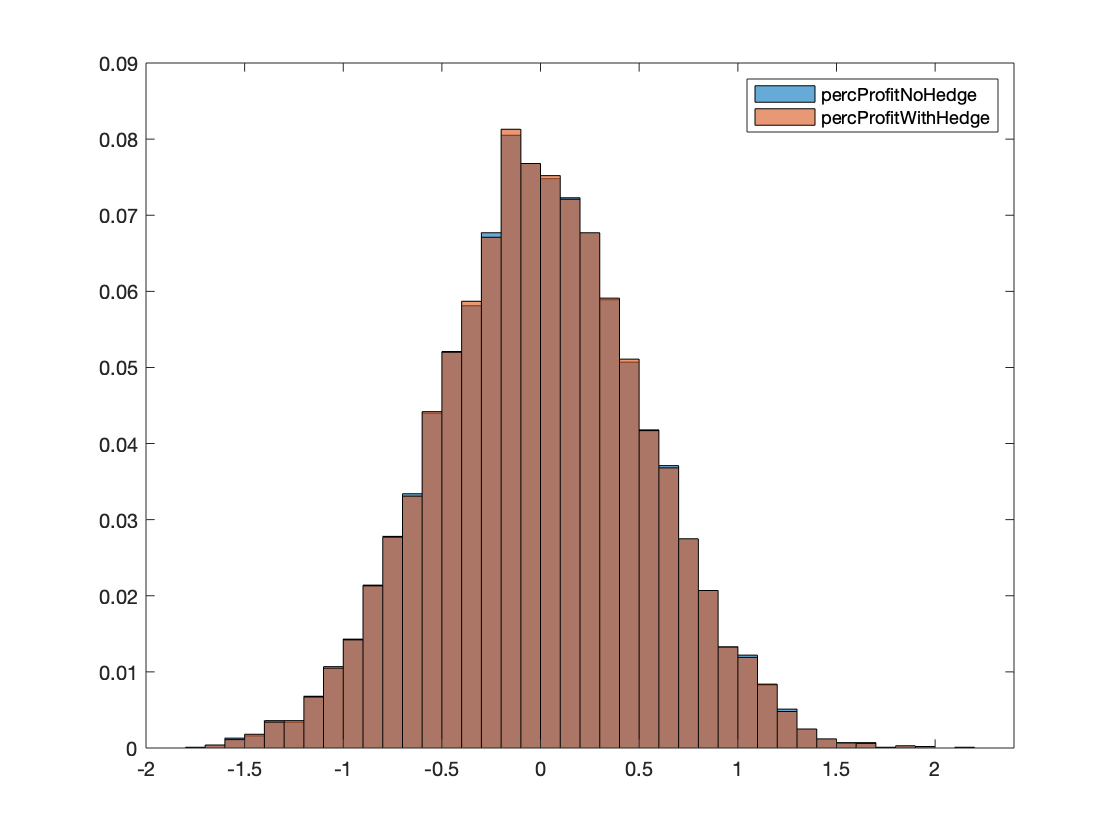

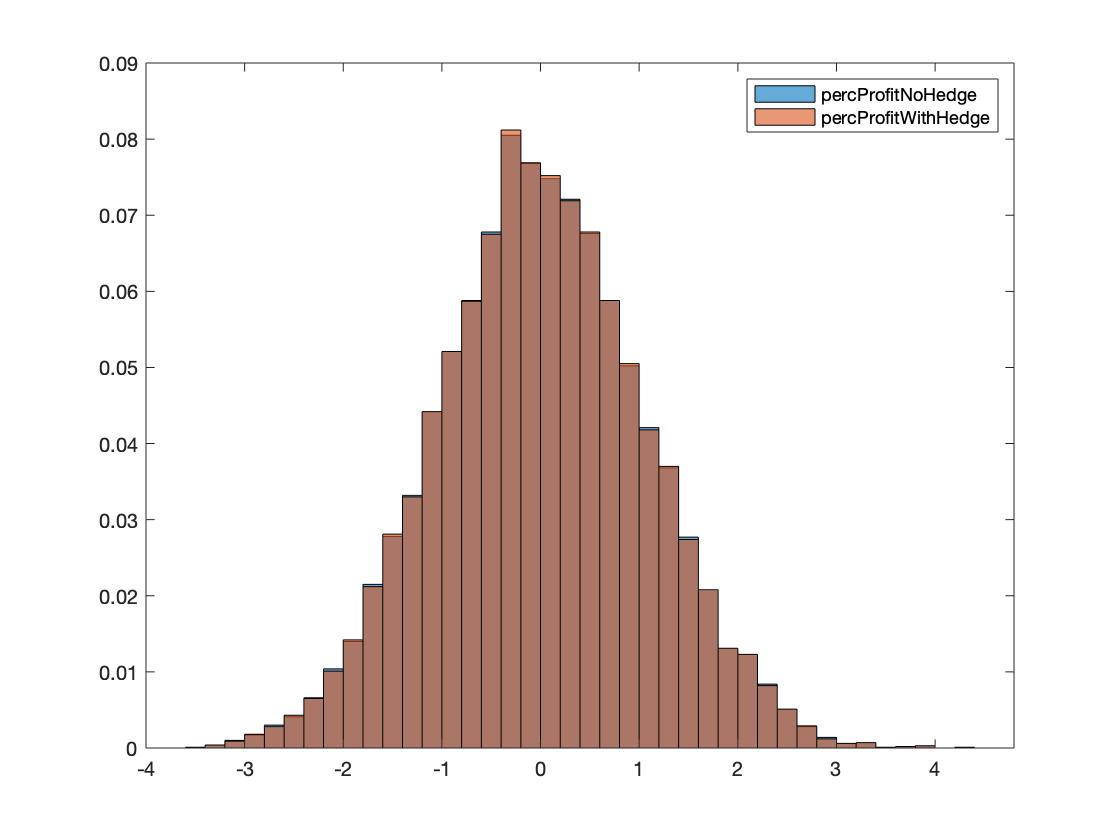

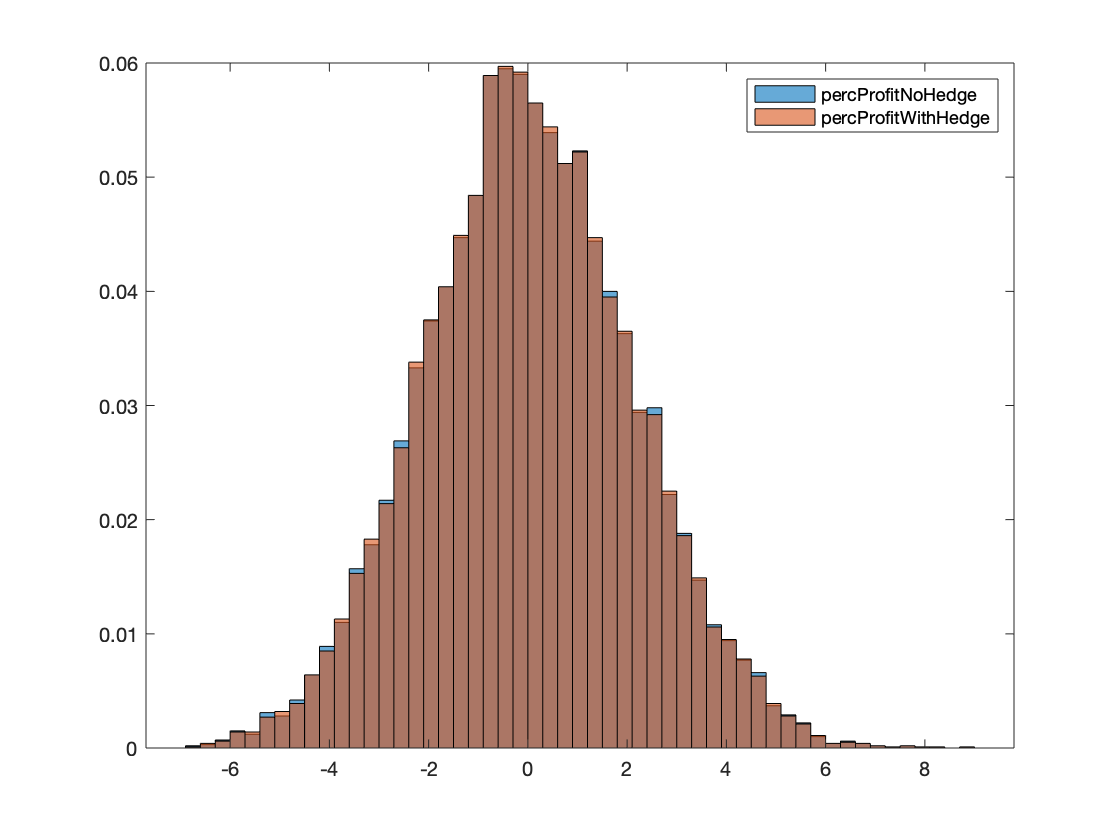

T=table('RowNames',{'VaR','VarNoHedge','CVaR','CVarNoHedge'});
for diff = 1:length(scale)
    seed = 'default';
    num_scenari = 10000;%10000
    mu = zeros(1,4);
    sigma = 0.001*scale(diff);
    Sigma = eye(4)*(sigma^2);
    rng(seed) % For reproducibility
    betaVariation = mvnrnd(mu,Sigma,num_scenari);
    
    percProfit = zeros(num_scenari,1);
    percProfitNoHedge = zeros(num_scenari,1);
    for s = 1:num_scenari
        [newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation(s,:),phi,'swap',fixed,last_rate);
        percProfit(s) = (newValuePosition-priceBondOriginal)/priceBondOriginal*100;
        percProfitNoHedge(s) = (priceBondNew-priceBondOriginal)/priceBondOriginal*100;
    end
    figure
    histogram(percProfitNoHedge,'Normalization','probability')
    hold on
    histogram(percProfit,'Normalization','probability')
    legend('percProfitNoHedge','percProfitWithHedge')
    hold off
    for prob=1:length(probabilities)
        id=floor(num_scenari*(1-probabilities(prob)));
        percProfit_sort = sort(percProfit);
        VaR(prob) = percProfit_sort(id);
        CVaR(prob) = mean(percProfit_sort(1:id));
        percProfitNoHedge_sort = sort(percProfitNoHedge);
        VaRNoHedge(prob) = percProfitNoHedge_sort(id);
        CVaRNoHedge(prob) = mean(percProfitNoHedge_sort(1:id));
    end
    tab(1,:) = VaR;
    tab(2,:) = VaRNoHedge;
    tab(3,:) = CVaR;
    tab(4,:) = CVaRNoHedge;
    
    T = addvars(T,tab,'NewVariableNames',num2str(sigma));
end

disp(T)

                            0.001                      0.002                      0.004         
                   _______________________    _______________________    _______________________

    VaR            -0.67    -0.86    -1.21    -1.33    -1.71    -2.41    -2.65    -3.39    -4.76
    VarNoHedge     -0.67    -0.86    -1.22    -1.34    -1.72    -2.41    -2.66    -3.40    -4.77
    CVaR           -0.92    -1.07    -1.38    -1.82    -2.13    -2.73    -3.60    -4.21    -5.38
    CVarNoHedge    -0.92    -1.07    -1.38    -1.83    -2.14    -2.74    -3.61    -4.22    -5.39



**(POSSIBILE CHE COPRA COSì BENE?? PERCHè I VALORI VENGONO COSì UGUALI??? HELP!)**

## Appendice

### **Funzione***** fixed_duration***

La funzione *fixed_duration *ha lo scopo di calcolare al tempo iniziale* t=0*, le dollar duration del prezzo di un bond rispetto ai parametri beta, che vanno a definire la curva dei tassi. Queste possono essere interpretate in modo molto semplice come delle sensitività al variare del singolo parametro beta proprio perché stiamo calcolando delle derivate. Se consideriamo un bond che al tempo $T_i$ paga cedole $F_i$o il valore nominale alla maturità, allora il suo prezzo sarà dato dalla formula:

                 
$$P=\sum_i  F_i \exp(-T_i R(0, t_i))$$


A questo punto, se scegliamo di utilizzare il modello di Svensson (o eventualmente quello di Nelson e Siegel dove l’ultima dollar duration ovviamente è nulla) per la curva dei tassi, possiamo calcolare facilmente le derivate, che sono date dalle seguenti formule:


$$D_0=- \sum_i T_i F_i exp(-T_i R(0, T, T_i))$$



$$D_1=\sum_i T_i \left[ \frac {1-exp\left(-\frac{T_i}{\tau_1}\right)}{\frac{T_i}{\tau_1}} \right] F_i exp(-T_i R(0, T_i))$$



$$D_2=\sum_i T_i \left[ \frac {1-exp\left(-\frac{T_i}{\tau_1}\right)}{\frac{T_i}{\tau_1}} -exp\left(-\frac{T_i}{\tau_1} \right)\right] F_i exp(-T_i R(0, T_i))$$



$$D_3=\sum_i T_i \left[ \frac {1-exp\left(-\frac{T_i}{\tau_2}\right)}{\frac{T_i}{\tau_2}} -exp\left(-\frac{T_i}{\tau_2} \right)\right] F_i exp(-T_i R(0, T_i))$$


La funzione riceve in input il tempo t_0 in cui ci troviamo e vogliamo valutare le sensitività, un vettore che contiene il portafoglio con la struttura descritta precedentemente, la formula per calcolare la struttura dei tassi ed infine esplicitamente i parametri che la caratterizzano quindi nell’ordine il vettore con i due parametri di scala e il vettore con i beta. La funzione restituisce in output il prezzo del portafoglio e tutte le derivate. Quando scegliamo di utilizzare la formula di Nelson-Siegel, l’ultima derivata viene settata a *NaN*.

Nel caso in cui il portafoglio sia composto da diversi bond, per ogni bond vengono calcolate le diverse sensitività ed infine, le beta-sensitività del portafoglio di bond sono uguali alla somma delle diverse beta-sensitività dei singoli bond pesata dal numero di ogni bond presente nel portafoglio. Prima di calcolare le diverse derivate e anche il prezzo è necessario calcolare l’importo di ciascuna cedola e il tempo in cui queste vengono pagate. Ovviamente se si tratta di uno ***zero***, abbiamo un unico pagamento pari al valore nominale alla maturità. Se invece si tratta di un ***bond*** che paga cedole, possiamo calcolare il valore di ogni cedola andando a moltiplicare il valore nominale per tasso di capitalizzazione che corrisponde al rapporto tra il tasso annuale di capitalizzazione e il numero di pagamenti che avvengono in un anno. In questo ultimo caso, per calcolare i tempi in cui avvengono i singoli pagamenti dobbiamo distinguere ulteriormente due casi. Il primo, è quando ci troviamo in un istante in cui la maturità del bond può essere raggiunta con un multiplo esatto del numero di pagamenti in anno e questo vuol dire che ci troviamo in un istante in cui è stata appena staccata una cedola o alla creazione del bond, quindi basterà guardare al numero di pagamenti in un anno per capire quando ci sarà il prossimo pagamento (ad esempio se ho un bond che paga cedole semestrali e la maturità è 18 mesi, il prossimo pagamento sarà tra sei mesi). Se invece al contrario, la maturità non è un multiplo del numero di pagamenti in un anno, vuol dire che ci troviamo in un istante in cui è passato già del tempo dall’ultimo stacco di una cedola o dalla creazione del bond, quindi il prossimo pagamento avverrà prima (se ad esempio un bond paga cedole semestrali e la maturità è 14 mesi, il prossimo pagamento ci sarà tra due mesi). Dopo aver calcolato gli istanti in cui avvengono i pagamenti, possiamo andare a valutare il valore dei tassi andando a sostituire nella formula di r che abbiamo passato alla funzione. Infine sostituendo nelle opportune formule riusciamo a calcolare il prezzo e le derivate rispetto ai beta.

function [price, D_0, D_1, D_2, D_3] = fixed_duration(t_0, portfolio, r, tau, betaValues)
%DETTAGLI PORTAFOGLIO
%quanti bond nel portafoglio
%quanti bond di quel tipo
%maturità in anni
%face value
%cedola annuale
%numero capitalizzazioni in un anno

% r è la formula della struttura per scadenza
% tau_1 parametro
%betaValues sono collegati alla struttura per scadenza

I=floor(portfolio(1));
N=portfolio(2:(2+I-1));
prices=zeros(1, I);
d_0=zeros(1, I);
d_1=zeros(1, I);
d_2=zeros(1, I);
d_3=zeros(1, I);
tau_1 = tau(1);

if length(tau)~=1 && betaValues(4)~=0 %usiamo la correzione di Svensson 
    tau_2 = tau(2);
end

for i=0:(I-1)
    T=portfolio(I+2+4*i);
    faceValue=portfolio(I+3+4*i);
    annualCoupon=portfolio(I+4+4*i);
    NPayments=portfolio(I+5+4*i);
    
    if NPayments==0
        c=0;
    else
    c=annualCoupon/NPayments*faceValue;
    end
    if mod(T, 1/NPayments)==0
        n=NPayments*T-1; %numero di pagamenti escluso quello della maturità
        time=linspace(t_0, T, n+2);
        time(1)=[];
    else
        t_1=mod(T, 1/NPayments);
        n=floor(NPayments*T);
        time=linspace(t_1, T, n+1);
    end
    termStructure=zeros(1, length(time));
    for j=1:length(time)
        termStructure(1, j)=r(betaValues,tau,time(j));
        
    end
    t=time.*termStructure;
    prices(1, i+1)=c*sum(exp(-(t(1:n)-t_0)))+(c+faceValue)*exp(-(t(n+1)-t_0));
    
    %derivata parziale del prezzo rispetto beta_0
    d_0(1, i+1)=-((c*sum(time(1:n).*exp(-t(1:n)-t_0)))+(time(n+1)*(c+faceValue)*exp(-(t(n+1)-t_0))));
    d_1(1, i+1)=-((c*sum(time(1:n).*exp(-t(1:n)-t_0).*(1-exp(-time(1:n)/tau_1))./(time(1:n)/tau_1)))...
        +((c+faceValue)*time(n+1).*exp(-t(n+1)-t_0).*(1-exp(-time(n+1)/tau_1))./(time(n+1)/tau_1)));
    d_2(1, i+1)=-((c*sum(time(1:n).*exp(-t(1:n)-t_0).*((1-exp(-time(1:n)/tau_1))./(time(1:n)/tau_1)-exp(-time(1:n)/tau_1))))...
        +((c+faceValue)*time(n+1).*exp(-t(n+1)-t_0).*((1-exp(-time(n+1)/tau_1))./(time(n+1)/tau_1)-exp(-time(n+1)/tau_1))));
    if length(tau)~=1 && betaValues(4)~=0
        d_3(1, i+1)=-((c*sum(time(1:n).*exp(-t(1:n)-t_0).*((1-exp(-time(1:n)/tau_2))./(time(1:n)/tau_2)-exp(-time(1:n)/tau_2))))...
            +((c+faceValue)*time(n+1).*exp(-t(n+1)-t_0).*((1-exp(-time(n+1)/tau_2))./(time(n+1)/tau_2)-exp(-time(n+1)/tau_2))));
    end
    
end
price=sum(N.*prices); %valore del bond

% beta sentitivities
D_0=sum(N.*d_0); %dollar duration
D_1=sum(N.*d_1);
D_2=sum(N.*d_2);
if length(tau)~=1 && betaValues(4)~=0
    D_3=sum(N.*d_3);
else
    D_3=NaN;
end
end


### **Funzione *****price_duration***

La funzione viene utilizzata all’interno dell’altra funzione *swap_duration*, per calcolare appunto il valore di uno swap. Sappiamo che il singolo swap può essere visto come la sovrapposizione di due parti: una relativa al tasso di interesse fisso e l’altra al tasso di interesse variabile. Quindi la funzione, oltre a ricevere i parametri fondamentali per calcolare il prezzo (t_0, il portafoglio, la struttura dei tassi e i relativi parametri), riceve anche una stringa che indica se calcolare il valore di un bond con cedola fissa o variabile. In questo ultimo caso è necessario passare alla funzione un ulteriore parametro che rappresenta il tasso floating, utile per calcolare il valore del pagamento della prossima cedola.  Se ci troviamo nel caso in cui il tasso è fisso, calcoliamo gli istanti di tempo in cui avvengono i pagamenti, il valore delle cedole e poi utilizziamo le formule per la capitalizzazione nel continuo per calcolare il prezzo, la duration e la dollar duration. Se invece i flussi di cassa sono stocastici, non abbiamo bisogno di trovare tutti i tempi in cui avvengono i pagamenti, perché sappiamo che un bond floater viene scambiato alla pari negli istanti di reset, quindi l’unica cosa di cui abbiamo bisogno è andare a trovare il tempo del prossimo reset. In conclusione quindi, la duration sarà data dalla differenza tra il tempo del prossimo reset e il tempo t_0. Infine, la funzione restituisce una variabile *K *che coincide con lo swap rate quando non passiamo alla funzione un asset che ha già definito un tasso di capitalizzazione annuale, quindi con il tasso di cedola tale per cui il bond a tasso fisso vende alla pari: ***par yield***. Infine, la variabile last_rate restituisce, solo quando non definiamo il tasso di capitalizzazione annuale e quindi vuol dire che stiamo creano lo swap in questo momento, il valore del tasso all’istante del prossimo reset, calcolando con la funzione dei tassi. Proprio questo tasso viene utilizzato per calcolare il valore della prossima cedola. In caso contrario non viene aggiornato. **(DA CONTROLLARE BENE)**

function [price, D, dollar_duration, last_rate, k] = price_duration(t_0, portfolio, r, tau, betaValues, type, last_rate)

I=floor(portfolio(1));
N=portfolio(2:(2+I-1));
prices=zeros(1, I);
durations=zeros(1, I);


for i=0:(I-1)
    T=portfolio(I+2+4*i);
    faceValue=portfolio(I+3+4*i);
    annualCoupon=portfolio(I+4+4*i);
    NPayments=portfolio(I+5+4*i);
    
    if strcmp(type,'fixed')%~exist('last_rate','var') %il portafoglio è costituito da bond
        if mod(T, 1/NPayments)==0
            n=NPayments*T-1; %numero di pagamenti escluso quello della maturità
            time=linspace(t_0, T, n+2);
            time(1)=[];
            
        else
            t_1=mod(T, 1/NPayments);
            n=floor(NPayments*T);
            time=linspace(t_1, T, n+1);
            
        end
        termStructure=zeros(1, length(time));
        for j=1:length(time)
            termStructure(j)=r(betaValues,tau,time(j));
        end
        
        t=time.*termStructure;
        if ~isnan(annualCoupon)
            c=annualCoupon/NPayments*faceValue;
        else    %calcoliamo lo swap rate
            k=NPayments*(1-exp(-T*termStructure(length(termStructure))))/sum(exp(-t(1:length(termStructure))));
            c=k*faceValue/NPayments;
        end

        prices(1, i+1)=c*sum(exp(-(t(1:n)-t_0)))+(c+faceValue)*exp(-(t(n+1)-t_0));
        durations(1, i+1)=1/prices(1, i+1)*(sum(c*(time(1:n)-t_0).*exp(-(t(1:n)-t_0)))+(c+faceValue)*(time(n+1)-t_0)*exp(-(t(n+1)-t_0)));
        
    else          %il portafoglio è costituito da floater
        if mod(T,1/NPayments)==0
            next_reset=1/NPayments;
            
        else
            next_reset=mod(T,1/NPayments);
        end
        
        % calcolo originale, se ci fosse annualCoupon vuol dire che
        % siamo durante un calcolo sugli shock dei beta
        if isnan(annualCoupon)
            last_rate = r(betaValues,tau,next_reset);
        end
        c=faceValue*(exp(last_rate/NPayments)-1);
        prices(1, i+1)=(c+faceValue)*exp(-(next_reset-t_0)*r(betaValues,tau,next_reset));
        durations(1, i+1)=(next_reset-t_0);
    end
    
    price=sum(N.*prices);
    D=1/price*sum(N.*prices.*durations);
    dollar_duration=D*price;
    
    
end
if ~exist('last_rate','var')
    last_rate = NaN;
end
if ~exist('k','var')
    k = NaN;
end
end


### **Funzione***** swap_duration***

La funzione calcola il prezzo, la dollar duration, il tasso swap e il valore del tasso utilizzato nell’ultimo reset, quando passiamo un portafoglio di swap, il tempo t_0 in cui vogliamo calcolarli e la struttura dei tassi. La funzione chiama due volte la funzione *price_duration, *la prima volta per il prezzo “fixed”, mentre la seconda volta quello “flotater”. Infine a seconda del punto di vista che stiamo considerando, valuta il prezzo e la dollar duration. Poiché lo swap nel momento in cui viene creato ha valore nullo (e nessuno ci assicura che il suo valore non possa essere zero anche dopo essere stato creato) la definizione classica di duration non può essere applicata.

function [p_swap,Dd_swap,k,last_rateUsed] = swap_duration(t_0, portfolio, r, tau, betaValues, fixed, last_rate)
%swap_duration(fixed, t_0, T, faceValue, NPayments, r, tau, betaValues, last_rate)

%Argomenti in input: 
%fixed=variabile booleana per stabilire il punto di vista fixed/floater
%t_0=istante di tempo in cui voglio calcolare il valore del portafoglio coperto
%portfolio=[NDifferentBond, NBond, T, faceValue, annualCoupond, NPayments]
%termStructure=quella che conosco oggi
%last_rate= per calcolare il prossimo pagamento del floater

%portfolio=[1, 1, T, faceValue, NaN, NPayments];
[p_fixed, ~, Dd_fixed,~,k]=price_duration(t_0, portfolio, r, tau, betaValues, 'fixed');
[p_float, ~, Dd_float,last_rateUsed,~]=price_duration(t_0, portfolio, r, tau, betaValues, 'floater',last_rate);

if fixed==true                          %dal punto di chi paga fisso
    p_swap=p_float-p_fixed;
    Dd_swap=Dd_float-Dd_fixed;
else
    p_swap=p_fixed-p_float;
    Dd_swap=Dd_fixed-Dd_float;
end
end

### **Funzione***** portfolioShock***

La funzione *portfolioShock* ha lo scopo di valutare il valore di una posizione coperta presa prima che si verifichi una variazione nella struttura dei tassi, quindi i due attori principali in questa valutazione sono il portafoglio di bond o il singolo bond che siamo interessati ad immunizzare e il numero di unità dello specifico strumento di hedging in cui abbiamo deciso di investire.

Gli argomenti di input della funzione sono:

- t_0: l’istante di tempo in cui ci troviamo

- bond: il portafoglio di bond o il singolo bond che siamo interessati a coprire

- hedge: lo strumento di hedging che vogliamo utilizzare

- r: la formula della struttura dei tassi che vogliamo utilizzare (Nelson-Siegel o Svensson)

- tau: il vettore con i parametri di scala

- betaValues: il vettore con i parametri beta che vanno a definire la curva dei tassi

- betaVariation: il vettore con le variazioni dei beta contro cui vorremmo essere protetti

- phi: il numero di unità dello strumento di hedging in cui abbiamo investito per coprire il nostro portafoglio

- type: un parametro opzionale che serve per capire se stiamo coprendo con un bond o con uno swap

- fixed: una variabile booleana opzionale che ci dice se il valore dello swap va considerato dal punto di vista “fixed”

- last_rate: un ultimo parametro opzionale che serve nel caso in cui decidiamo di coprirci con uno swap per calcolare l’importo della prossima cedola.

Invece, gli argomenti di output sono:

- newValuePosition: il valore della posizione coperta dopo la variazione della struttura per scadenza

- priceBondOriginal: il prezzo del bond che vorremmo coprire *prima* della variazione nella struttura dei tassi

- priceBondNew: il prezzo del bond che vorremmo coprire *dopo* la variazione nella struttura dei tassi

La funzione inizialmente calcola il prezzo del bond prima e dopo la variazione nella struttura dei tassi per scadenza, richiamando la funzione *fixed_duration*. Successivamente, distingue il caso in cui decidiamo di fare una copertura usando dei bond oppure degli swap. Nel primo caso, calcola il prezzo dello zero o del portafoglio di zeri, ancora utilizzando la funzione *fixed_duration*, in base alle unità in cui abbiamo deciso di investire. Infine, calcola il valore della posizione coperta.

Quando invece scegliamo di proteggerci dalle variazioni andando ad utilizzare degli swap, abbiamo bisogno di richiamare la funzione *swap_duration*, ma la procedura per calcolare il valore della nuova posizione è esattamente la stessa.

function [newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation,phi,type,fixed,last_rate)


[priceBondOriginal, ~, ~, ~]=fixed_duration(t_0, bond, r, tau, betaValues);
[priceBondNew, ~, ~, ~]=fixed_duration(t_0, bond, r, tau, betaValues+betaVariation);

if exist('type','var') && strcmp(type,'swap')
    [priceSwapOriginal, ~,k,last_rateUsed]=swap_duration(t_0, hedge, r, tau, betaValues, fixed, last_rate);
    I=floor(hedge(1));
    for i=0:(I-1)
        hedge(I+4+4*i) = k; %diciamo qual è lo swap rate perché già definito e non influenzato dagli shock
    end
    [priceSwap, ~, ~, ~]=swap_duration(t_0, hedge, r, tau, betaValues+betaVariation, fixed, last_rateUsed);
    newValuePosition = priceBondNew + (priceSwap - priceSwapOriginal);
else
    hedge(2:2+hedge(1)-1)=phi;
    [priceZeroOriginal, ~, ~, ~]=fixed_duration(t_0, hedge, r, tau, betaValues);
    [priceZero, ~, ~, ~]=fixed_duration(t_0, hedge, r, tau, betaValues+betaVariation);
    newValuePosition = priceBondNew + (priceZero - priceZeroOriginal);
end

end